# Situacion Problema

Ángel Alexander Baez Flores

Angel Emiliano Vargas Carreto

Marco Armando Islas Brito

Osmar Enrique Sanchez Martinez

Roberto Castro Gomez

## Descripcion

**Primer entregable (fin de la segunda semana):** Un programa, de MATLAB, que grafique la aceleración y velocidad contra el tiempo y también contra la altura de las soluciones a la ecuación diferencial incluida abajo.

La ecuación se obtiene a partir de la segunda Ley de Newton, donde *v* es la velocidad de la Góndola, *Fg* es la fuerza de gravedad, *Fz* la fuerza debida a las corrientes de Eddy (que será considerada como proporcional a la velocidad), *m* es su masa, *t* el tiempo:


$$\frac{\textrm{dv}}{\textrm{dt}}-\frac{F_g -F_z }{m}=0$$


El primer entregable debe incluir una explicación de cómo se obtiene esta ecuación diferencial, de que implica que hay una "velocidad terminal" en el movimiento de la góndola, y que sucede con el movimiento cuando la velocidad inicial de la góndola es mayor que la velocidad terminal. 

# Solucion

## Programa

% Parámetros del problema
g = 9.81; % gravedad en m/s^2
m = 100; % masa de la góndola en kg
k = 50; % constante proporcional al frenado magnético, ajustada para mayor frenado
v0 = 0; % velocidad inicial en m/s
h0 = 0; % altura inicial en m (comenzando desde el suelo)
altura_total = 66; % altura total de la torre en m
tiempo_espera = 5; % tiempo de espera en la cima en segundos

% Calcular la velocidad terminal
vt = m * g / k;

% Fase de ascenso (velocidad constante)
t_ascenso = sqrt(2 * altura_total / g);
v_ascenso = altura_total / t_ascenso;
tspan_ascenso = linspace(0, t_ascenso, 100)';
v1 = v_ascenso * ones(size(tspan_ascenso));
h1 = cumtrapz(tspan_ascenso, v1);

% Fase de espera en la cima
t_espera = linspace(0, tiempo_espera, 50)';
h_espera = altura_total * ones(size(t_espera));

% Fase de descenso (con frenado magnético)
t_descenso = t_ascenso; % Usamos el mismo tiempo de ascenso como tiempo de descenso
tspan_descenso = linspace(0, t_descenso, 100)';

% Ecuación diferencial para la velocidad con frenado magnético
frenado_magnetico = @(t, v) g - (k/m) * v;

% Resolver la ecuación diferencial comenzando con velocidad cero
[t2, v2] = ode45(frenado_magnetico, tspan_descenso, 0);

% Calcular la altura durante el descenso
h2 = altura_total - cumtrapz(t2, v2);

% Ajustar las alturas para que no caigan por debajo de cero
h2(h2 < 0) = 0;

% Fase de frenado final para detener la góndola
t_frenado_final = 10; % Duración del frenado final en segundos, ajustada para una parada completa
t_total_frenado = linspace(0, t_frenado_final, 100)';
% Ajustar el frenado final para que no dependa solo de la gravedad sino también del frenado magnético residual
v_frenado_final = v2(end) * exp(-(k/m) * t_total_frenado); 
h_frenado_final = max(h2(end) - cumtrapz(t_total_frenado, v_frenado_final), 0); % Ajustar la altura para que no sea negativa

% Unir los tiempos y alturas de las tres fases (ascenso, espera y descenso con frenado final)
t_total = [tspan_ascenso; t_espera + tspan_ascenso(end); t2 + tspan_ascenso(end) + tiempo_espera; t_total_frenado + t2(end) + tspan_ascenso(end) + tiempo_espera];
h_total = [h1; h_espera; h2; h_frenado_final];
v_total = [v1; zeros(size(t_espera)); v2; v_frenado_final];

% Calcular la aceleración
a_ascenso = zeros(size(tspan_ascenso)); % Aceleración en el ascenso
a_espera = zeros(size(t_espera)); % Aceleración durante la espera
a_descenso = g - (k/m) * v2; % Aceleración durante el descenso
a_frenado_final = gradient(v_frenado_final, t_total_frenado); % Aceleración durante el frenado final

% Unir los valores de aceleración de todas las fases
a_total = [a_ascenso; a_espera; a_descenso; a_frenado_final];

% Calcular el jerk para cada fase
jerk_ascenso = abs(gradient(a_ascenso) ./ gradient(tspan_ascenso)); % jerk durante el ascenso
jerk_espera = zeros(size(t_espera)); % jerk durante la espera
jerk_descenso = abs(gradient(a_descenso) ./ gradient(t2)); % jerk durante el descenso
jerk_frenado_final = abs(gradient(a_frenado_final) ./ gradient(t_total_frenado)); % jerk durante el frenado final

% Suavizar el jerk para evitar valores extremos
jerk_total_g_per_s = [jerk_ascenso; jerk_espera; jerk_descenso; jerk_frenado_final]; % jerk total
jerk_total_g_per_s = movmean(jerk_total_g_per_s, 5); % suavizar el jerk

% Imprimir la velocidad final al llegar al piso
velocidad_final = v_total(end);
fprintf('La velocidad final al llegar al piso es %.2f m/s\n', velocidad_final);

La velocidad final al llegar al piso es 0.11 m/s


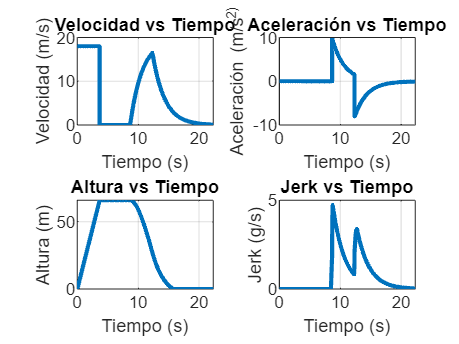


% Graficas de velocidad vs tiempo, aceleración vs tiempo, altura vs tiempo y jerk vs tiempo
figure;
subplot(2, 2, 1);
plot(t_total, v_total, 'LineWidth', 2);
title('Velocidad vs Tiempo');
xlabel('Tiempo (s)');
ylabel('Velocidad (m/s)');
grid on;

subplot(2, 2, 2);
plot(t_total, a_total, 'LineWidth', 2);
title('Aceleración vs Tiempo');
xlabel('Tiempo (s)');
ylabel('Aceleración (m/s^2)');
grid on;

subplot(2, 2, 3);
plot(t_total, h_total, 'LineWidth', 2);
title('Altura vs Tiempo');
xlabel('Tiempo (s)');
ylabel('Altura (m)');
grid on;

subplot(2, 2, 4);
plot(t_total, jerk_total_g_per_s, 'LineWidth', 2);
title('Jerk vs Tiempo');
xlabel('Tiempo (s)');
ylabel('Jerk (g/s)');
grid on;

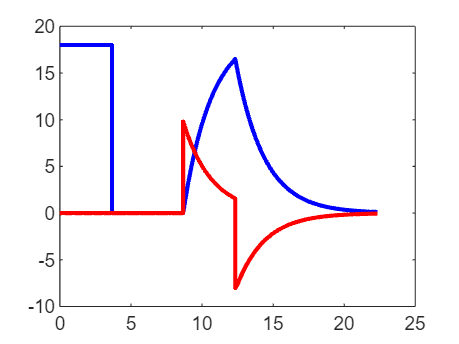



% Graficar velocidad, aceleración y jerk en función de la altura
figure;
plot(t_total, v_total, 'b', 'LineWidth', 2);
hold on;
plot(t_total, a_total, 'r', 'LineWidth', 2);

plot(t_total, jerk_total, 'g', 'LineWidth', 2);

Unrecognized function or variable 'jerk_total'.

plot(t_total, h_total, 'k', 'LineWidth', 2);
hold off;
legend({'v (m/s)', 'a (m/s^2)', 'jerk (g/s)', 'h(m)'});
xlabel('Tiempo (s)');
ylabel('m/s; m/s^2; g/s');
title('Velocidad, Aceleración, Jerk y Altura vs Tiempo');

## Explicacion

Resolvemos la ecuación diferencial usando `ode45`, una función adecuada para resolver ecuaciones diferenciales ordinarias. Posteriormente, cumtrapz calcula la altura acumulativa en cada punto de tiempo basado en la velocidad y la altura inicial. Finalmente, graficamos respecto de velocidad y aceleración contra el tiempo y contra la altura, proporcionando una visualización clara del comportamiento de la góndola bajo las fuerzas dadas.

***Derivación de la Ecuación Diferencial***

La ecuación dada es: $\frac{\textrm{dv}}{\textrm{dt}}-\frac{F_g -F_z }{m}=0$

Donde:

- $v$ es la velocidad de la góndola.

- $F_g$ es la fuerza de gravedad, que es $\textrm{mg}$, donde $g$ es la aceleración debida a la gravedad.

- $F_z$ es la fuerza debida a las corrientes de Eddy, que es proporcional a la velocidad $v$. Asumimos $F_z =\textrm{kv}$ , donde $k$ es una constante de proporcionalidad.

- $m$ es la masa de la góndola.

- $t$es el tiempo.

Sustituimos $F_g$ y $F_z$ : $\frac{\textrm{dv}}{\textrm{dt}}-\frac{\textrm{mg}-\textrm{kv}}{m}=0$ $\Rightarrow$ Simplificado: $\frac{\textrm{dv}}{\textrm{dt}}=g-\frac{k}{m}v$

Esta es una ecuación diferencial lineal de primer orden que podemos escribir como: $\frac{\textrm{dv}}{\textrm{dt}}+\frac{k}{m}v=g$

***Velocidad Terminal***

La velocidad terminal $v_t$ ocurre cuando la aceleración $\frac{\textrm{dv}}{\textrm{dt}}$ es cero. Esto sucede cuando la fuerza de arrastre $F_z$ iguala a la fuerza gravitacional $F_g$:

#### 
$$0=g-\frac{k}{m}v_t \Rightarrow v_t =\frac{\textrm{mg}}{k}$$


***Comportamiento del Sistema con Diferentes Velocidades Iniciales***

- Velocidad inicial menor que la velocidad terminal: La góndola acelerará hacia abajo hasta alcanzar la velocidad terminal.

- Velocidad inicial mayor que la velocidad terminal: La góndola desacelerará hasta alcanzar la velocidad terminal.

***Descripcion de Cumtrapz***

Cumtrapz calcula la integral acumulativa de un vector de datos de manera aproximada mediante la suma de áreas de trapecios formados entre puntos consecutivos del vector. Se utiliza para calcular la altura h en función del tiempo integrando la velocidad v acumulada sobre el intervalo de tiempo t. La velocidad es el cambio de posición con respecto al tiempo, por lo que la integración de la velocidad te da la posición (o altura en este caso). Este resultado se usa para trazar la gráfica de la altura en función del tiempo.